M130 Lab 5

Start by checking the image properties of your assigned image and loading it into MATLAB

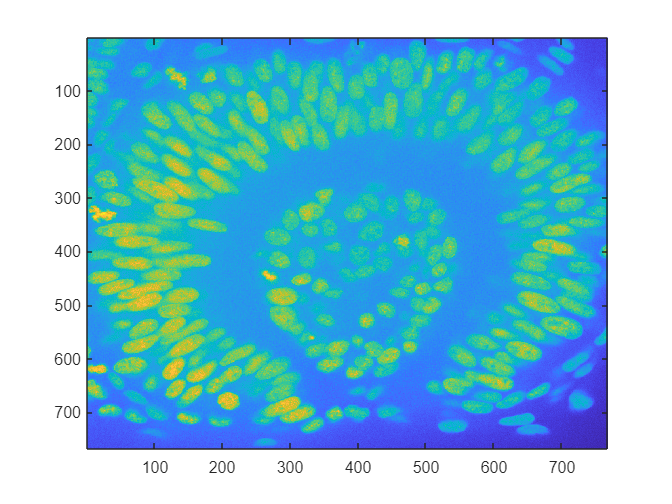

%Load your image, these are 2D images
img = imread('2D_Image_17.tif'); 
imagesc(img)

%Perform denoising on the image using a Gaussian blur, pick an appropriate
%value of c to reduce noise and aid in segmentation
ft_image = fft2(img);%complex values of the Fourier Transform
ft_image_real = abs(ft_image);%real values of the Fourier Transform
shift_ft_image = fftshift(ft_image); 


m = 20;
n = 20;
gaussian = zeros(m,n);
c = 3; % choosing c for the filter 
disp(['Here I am choosing 3 because I have chosen a blob ' ...
    'and found its pixel width and length to be 20x20, ' ...
    'and then I divide that number by 6. We can set the c to be that value.'])

Here I am choosing 3 because I have chosen a blob and found its pixel width and length to be 20x20, and then I divide that number by 6. We can set the c to be that value.



for x=1:n
    for y=1:m
        sq_dist = (x-n/2)^2 + (y-m/2)^2; % distance from the center pixel
        gaussian(y,x) = exp(-1*sq_dist/(2*c*c)); % division by the standard deviation.
    end
end
gaussian = gaussian./sum(gaussian(:)); % to normalize the kernel since we are taking discrete values. 
imagesc(gaussian)
colormap

ans =     0.2422    0.1504    0.6603
    0.2444    0.1534    0.6728
    0.2464    0.1569    0.6847
    0.2484    0.1607    0.6961
    0.2503    0.1648    0.7071
    0.2522    0.1689    0.7179
    0.2540    0.1732    0.7286
    0.2558    0.1773    0.7393
    0.2576    0.1814    0.7501
    0.2594    0.1854    0.7610


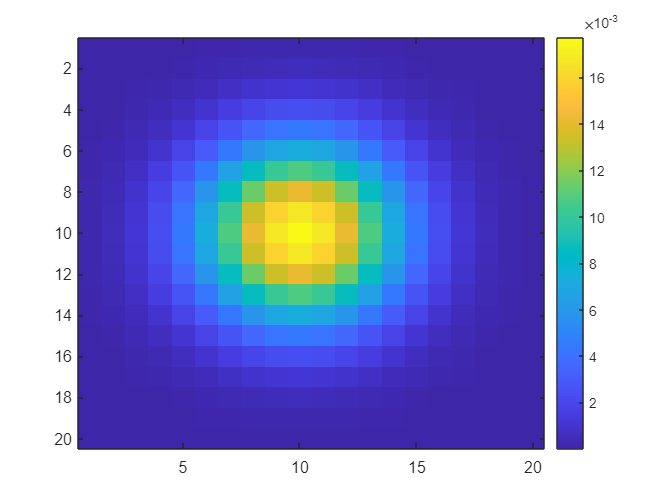

colorbar

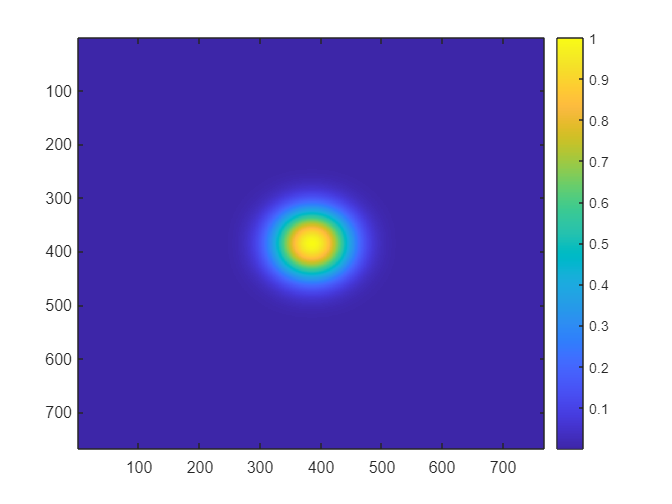

ft_gauss = fft2(gaussian, size(img,1),size(img,2));
shift_ft_gauss = fftshift(ft_gauss);
imagesc(log2(1+abs(shift_ft_gauss)))
colorbar

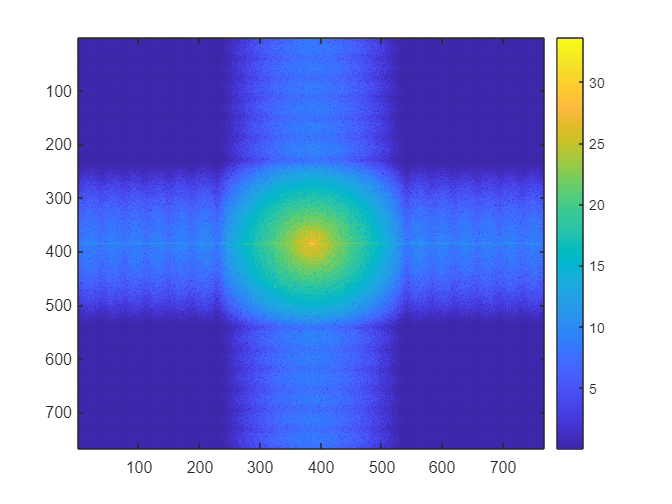

% Apply Gaussian filter over image, and see image in frequency domain. 
filtered_ft_img = shift_ft_image.*shift_ft_gauss; 
imagesc(log2(1+abs(filtered_ft_img)))
colorbar

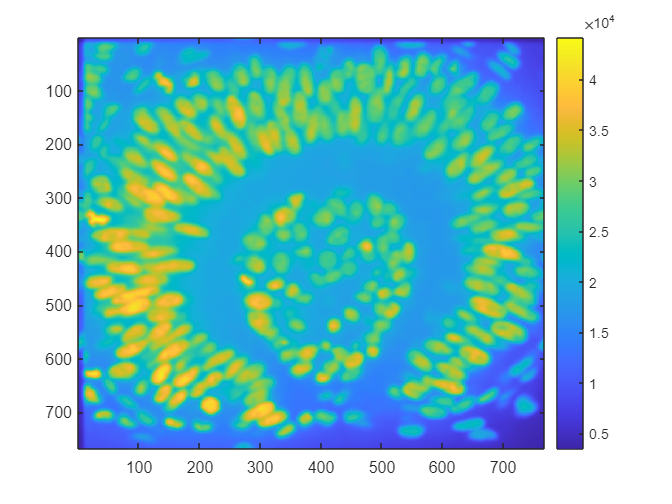

% Computing inverse fft of the image 
new_img = ifft2(ifftshift(filtered_ft_img)); 
imagesc(abs(new_img)) 
colorbar

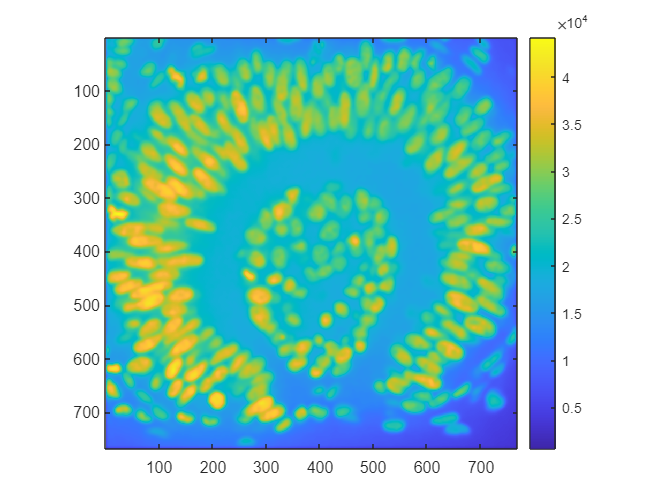

img_blur = conv2(img,gaussian,'same'); 
%from lecture by taking convolution, same steps, just another method
imagesc(img_blur)
colorbar
axis image

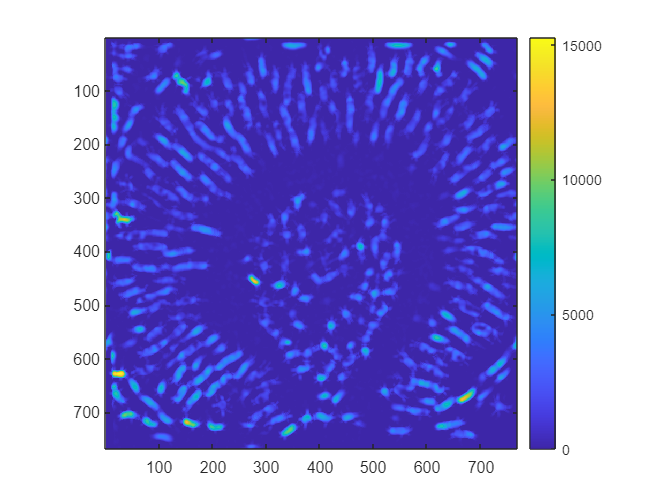

%Perform background subtraction by morphological opening.
% Pick a large radius for the strel function that
% would extend outside of any objects or
%clumps of objects in the foreground    
background = imopen(new_img, strel('disk', 9)); 
img_background = new_img - background; 
imagesc(img_background) 
colorbar 
axis image

%note: can do this part first before denoising.
% We denoise to get rid of the bright spots that might be
% characterized as foreground. 

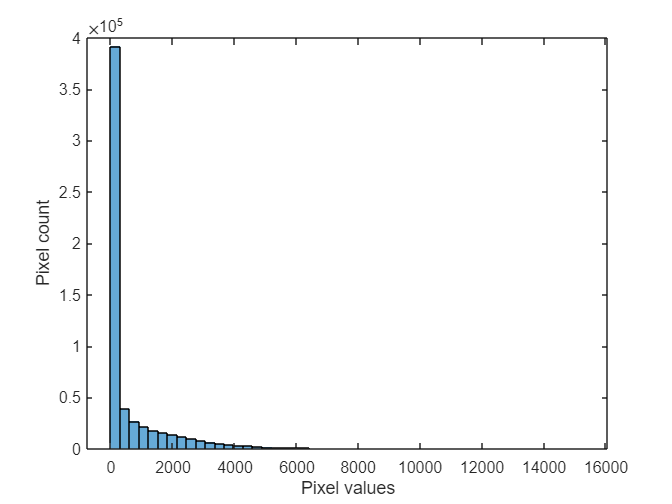

%Perform Intensity Thresholding
%Test manual, Otsu's and adaptive thresholding approaches and pick the one
%you like best to use for the rest of the lab

% picking a threshold by examining pixel value 
histogram(double(img_background(:)), 50)
xlabel('Pixel values')
ylabel('Pixel count')

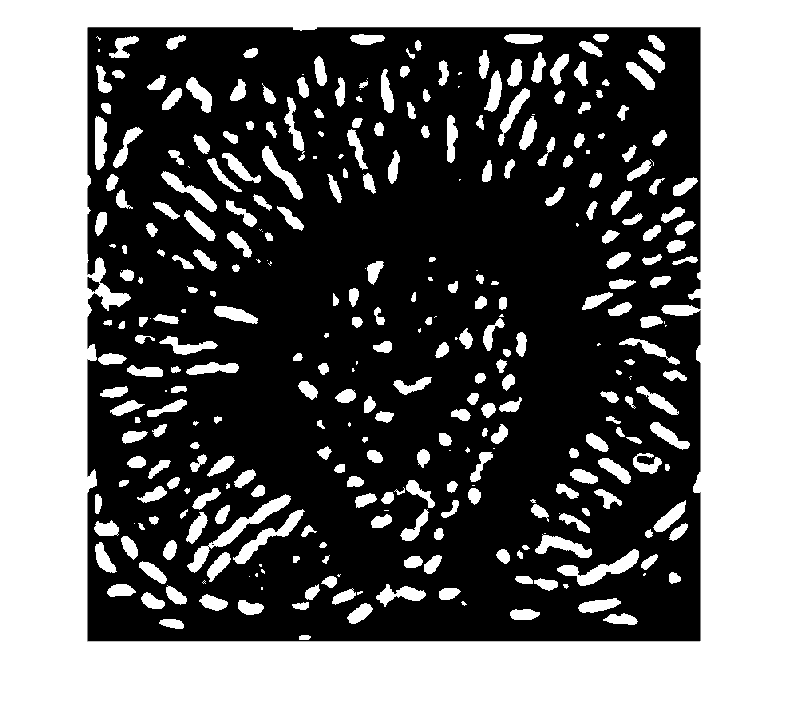

thresh = 1700; %this is the threshold because majority of the pixels are less than 1700
bw = img_background >thresh; 
imshow(bw)

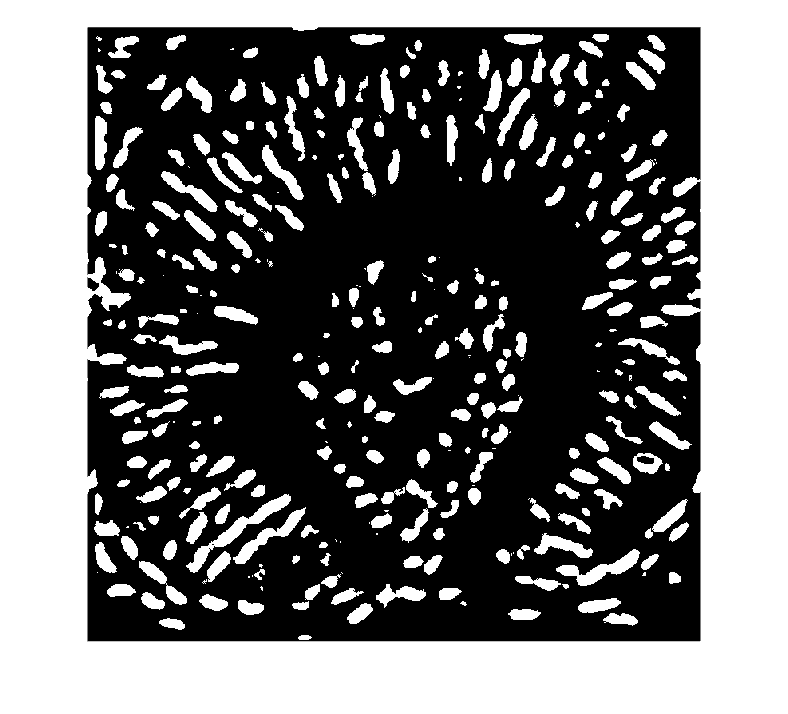

%This is Otsu's method
bw = imbinarize(uint16(img_background), 'global'); %many more pixels are characterized as foreground 
% not every pixel should contain object
imshow(bw)

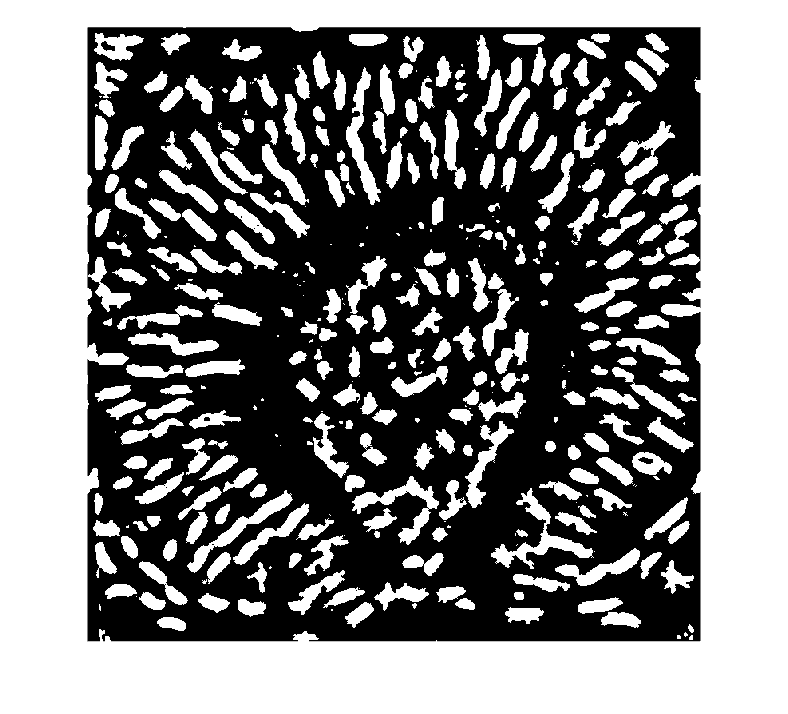

% And now we test the adaptive threshold method 
bw = imbinarize(uint16(img_background), 'adaptive');
%changing the global to adaptive, criteria is based on local background and
%local information 
imshow(bw)

% Adaptive thresholding method seems to perform better, we will use it
% for the rest of the lab. 

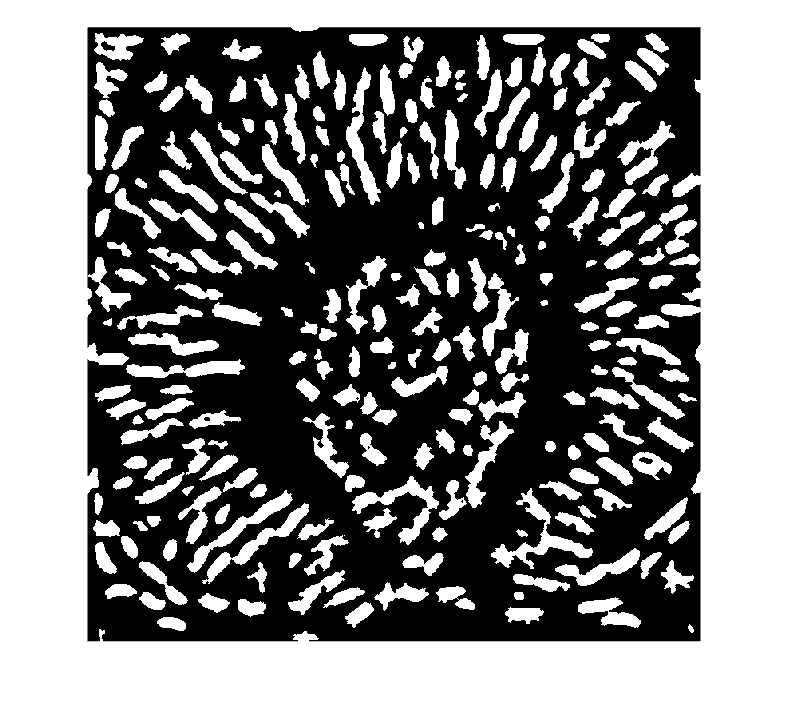

%Clean up the segmentation by mathematical morphology
bw = bwareaopen(bw, 50); % use bwareaopen to get rid of tiny isolated clusters of pixels
%first shrink the image, then do dilation to expand the image. 
bw = imclose(bw, strel('disk', 1));
% closing is doing the reverse order, to remove tiny noise pixels. 
imshow(bw)

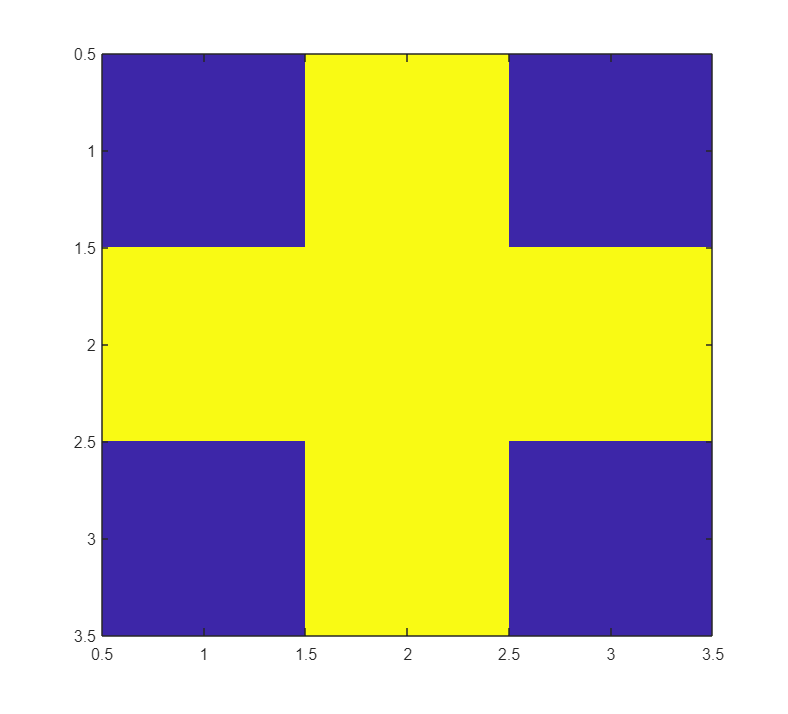

%creating a structuring element of radius = 1, which has a shape and size.
%SE is the object we will perform on for erosion and dilation. Imagine each
%square is a pixel. 
SE = strel('disk',1); 
imagesc(SE.Neighborhood)

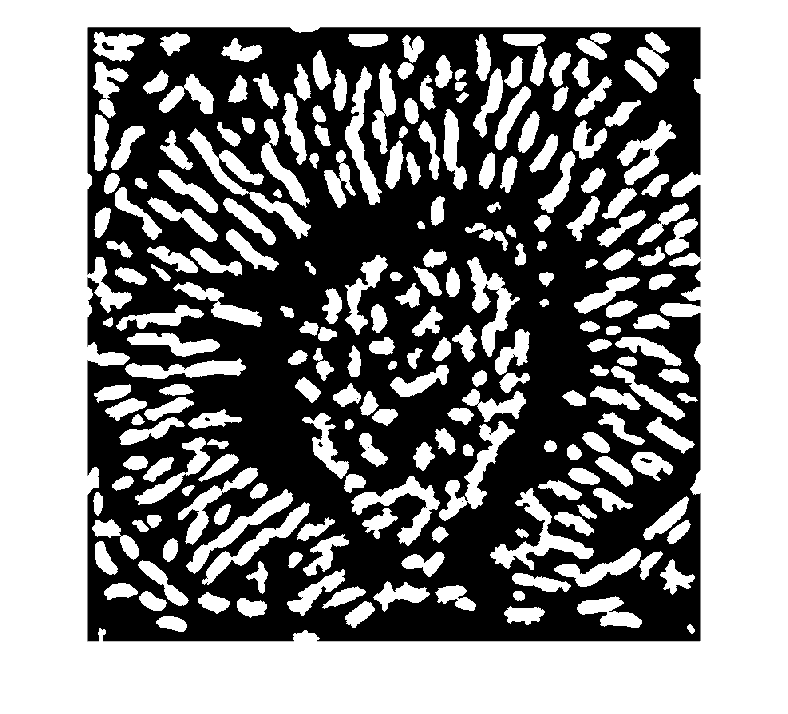

%perform dilation on binarized image SE, taking every center spot and
%dilating to all four points around it. We can specify how many times the
%expansion is happening. 
dilated = imdilate(bw, SE); 
imshow(dilated)

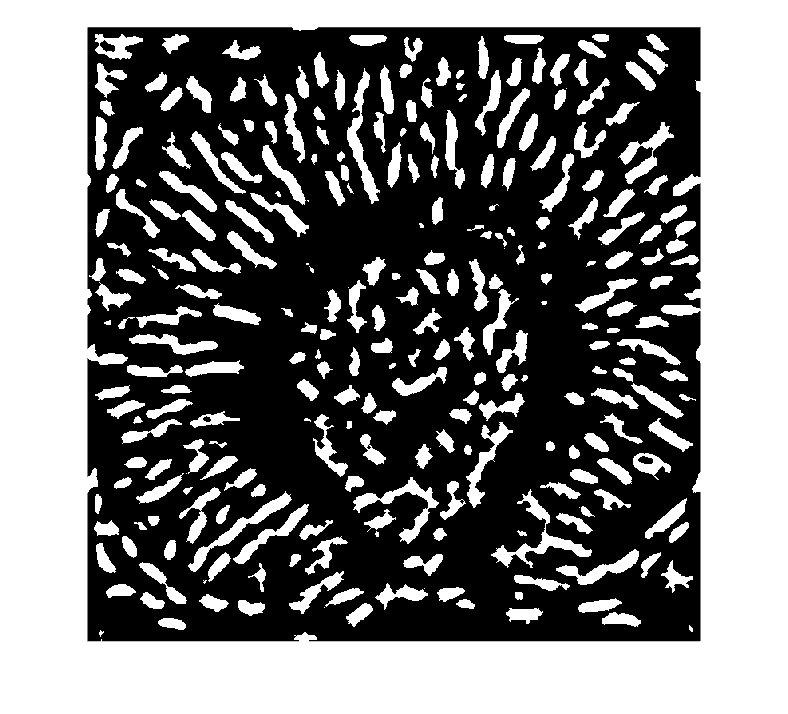

%eroded: erodes the grayscale, binary, or packed binary image using the structuring element SE
eroded = imerode(bw, SE); 
imshow(eroded)

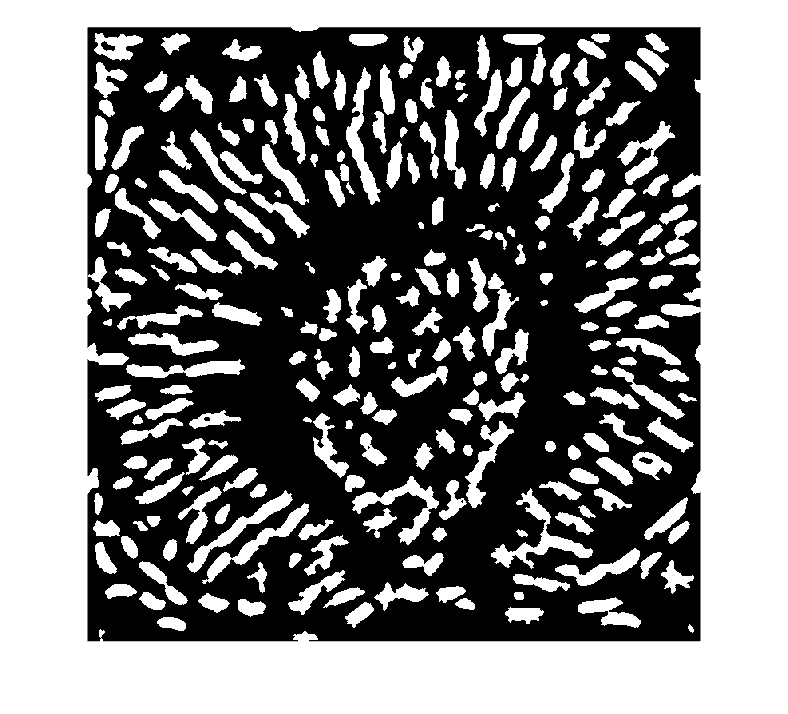

%imopen is erosion followed by a dilation, using the same structuring element for both operations
opened = imopen(bw, SE); 
imshow(opened)

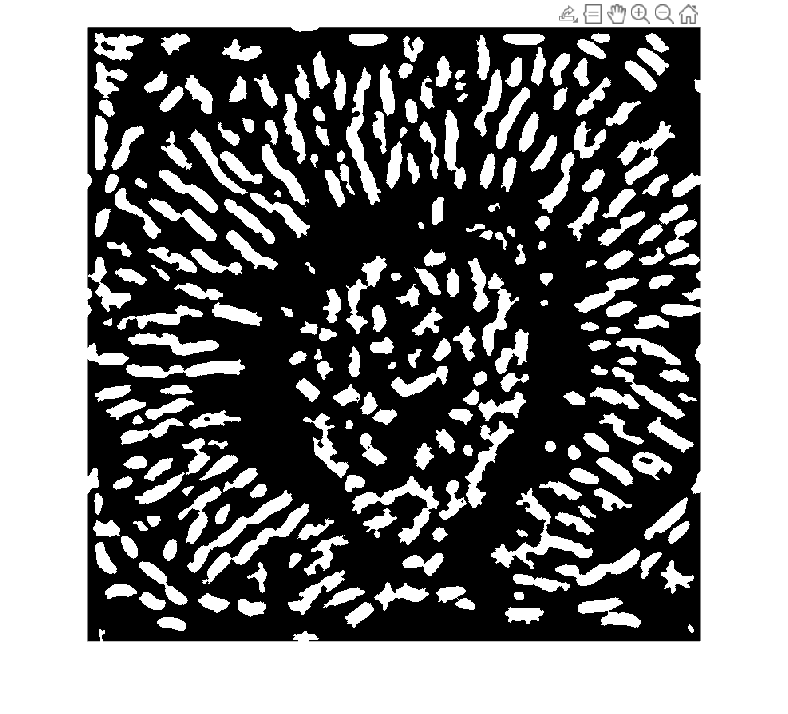

%imclose is an operation a dilation followed by an erosion, using the same structuring element for both operations
closed = imclose(bw, SE); 
imshow(closed)

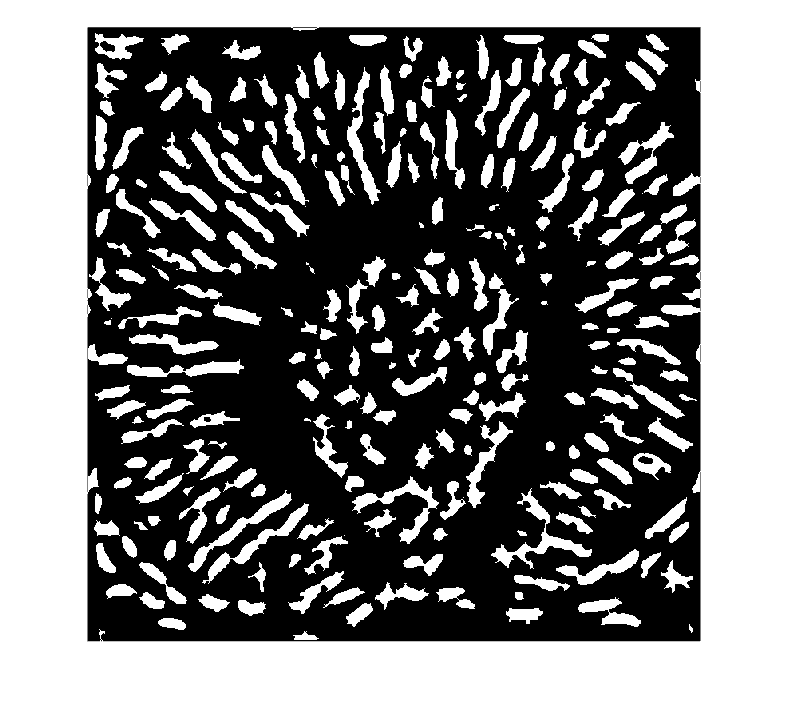

skel = bwmorph(bw, 'skel'); 
imshow(skel)

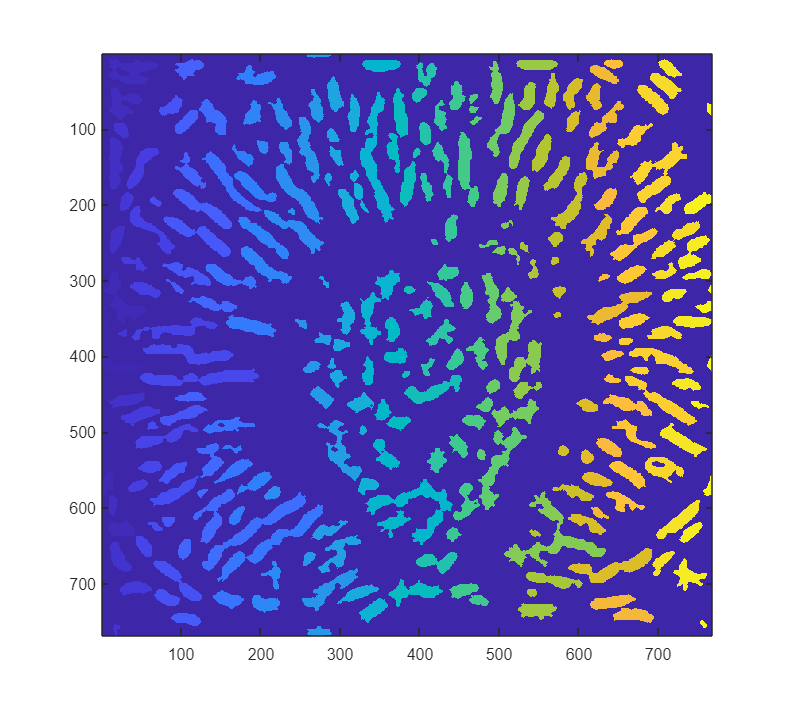

%Connected components labeling returns a label matrix and the number of
%objects
[L,N] = bwlabel(bw); 
%returns all connectd object as one value in the matrix, same color is the
%same group. 
imagesc(L)

disp(N) % there are 181 groups detected in the image 

   259



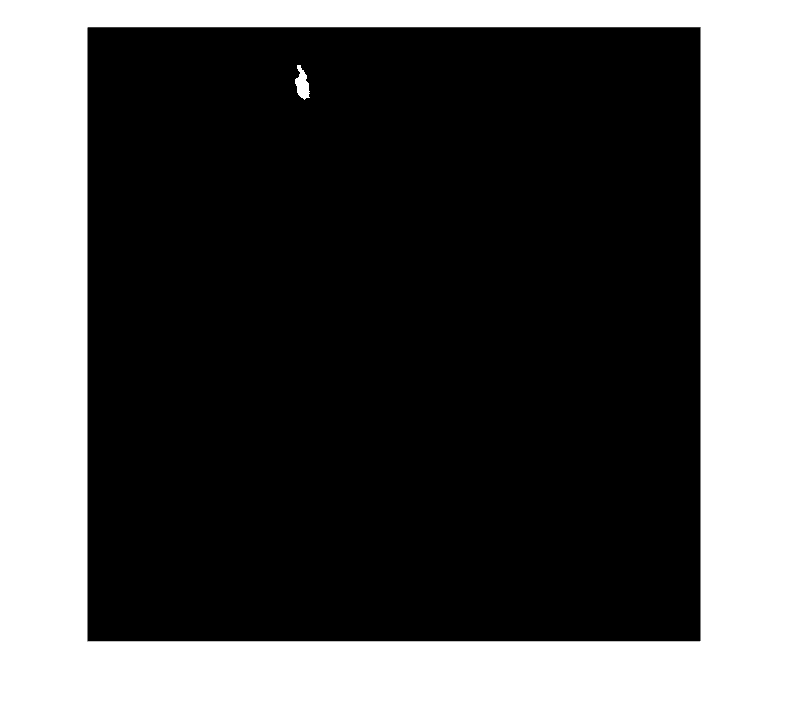

imshow(L == 90) % to extract individual objects by specifying the object number

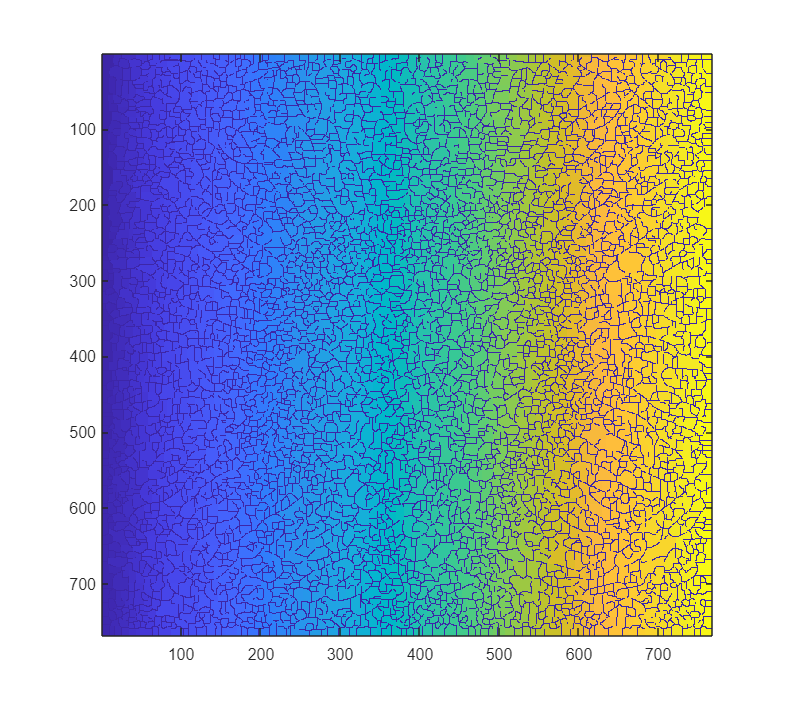

%From lecture, the watershed transform. 
gaussian = zeros(100);
m = 150;
n = 150;
c = 2.5;
for x = 1:n
    for y = 1:m
        gaussian(y,x) = exp(-1*((x-n/2)^2+(y-m/2)^2)/(2*c^2));
    end
end
gaussian = gaussian./sum(gaussian(:));

ddx = diff(gaussian,2,2);
ddy = diff(gaussian,2,1);

img_log = conv2(img,ddx,'same') + conv2(img,ddy,'same');

mask = imextendedmin(img_log,1.5);

img_log = imimposemin(img_log,mask);

W = watershed(img_log);
imagesc(W)

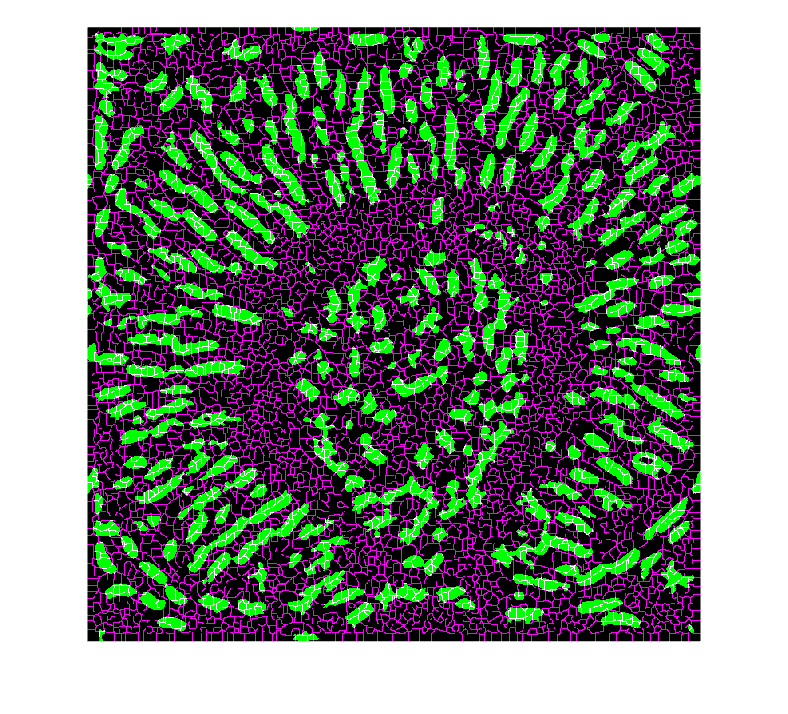

boundaries = W==0;
imshowpair(bw,boundaries)

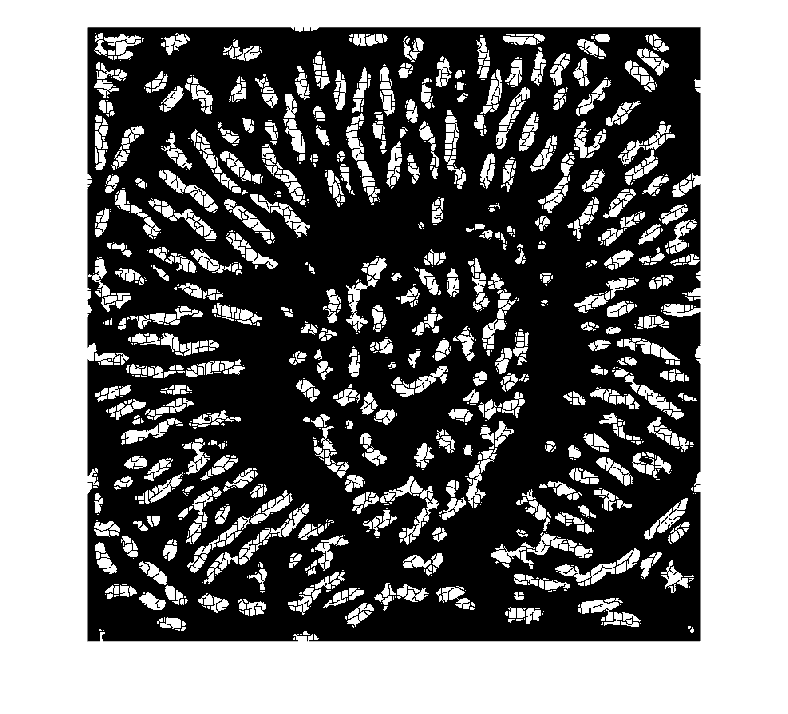

bw2 = bw;
bw2(boundaries) = 0;
imshow(bw2)

%Discuss the results, did the morphology changes improve segmentation quality at all? 
%What features of your image made it well or poorly suited to
%morphology-changes-based approaches?

print(['Firstly, adaptive thresholding was beneficial because of The morphology changes improved the segmentation quality because we are considering the local fractional region' ...
    'rather than the overall pixel intensity globally. Furthermore, I think dilation followed by an erosion by imclose worked the best because edges of the individual cells were accentuated' ...
    'by the dilation (rank increased by 1), so I would say this is a feature that was particularly suited to imclose morphology-changes-based approach.'])

Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most?

So far, everything seem to be working. I would need information on the watershed method. 